# **Question 2**

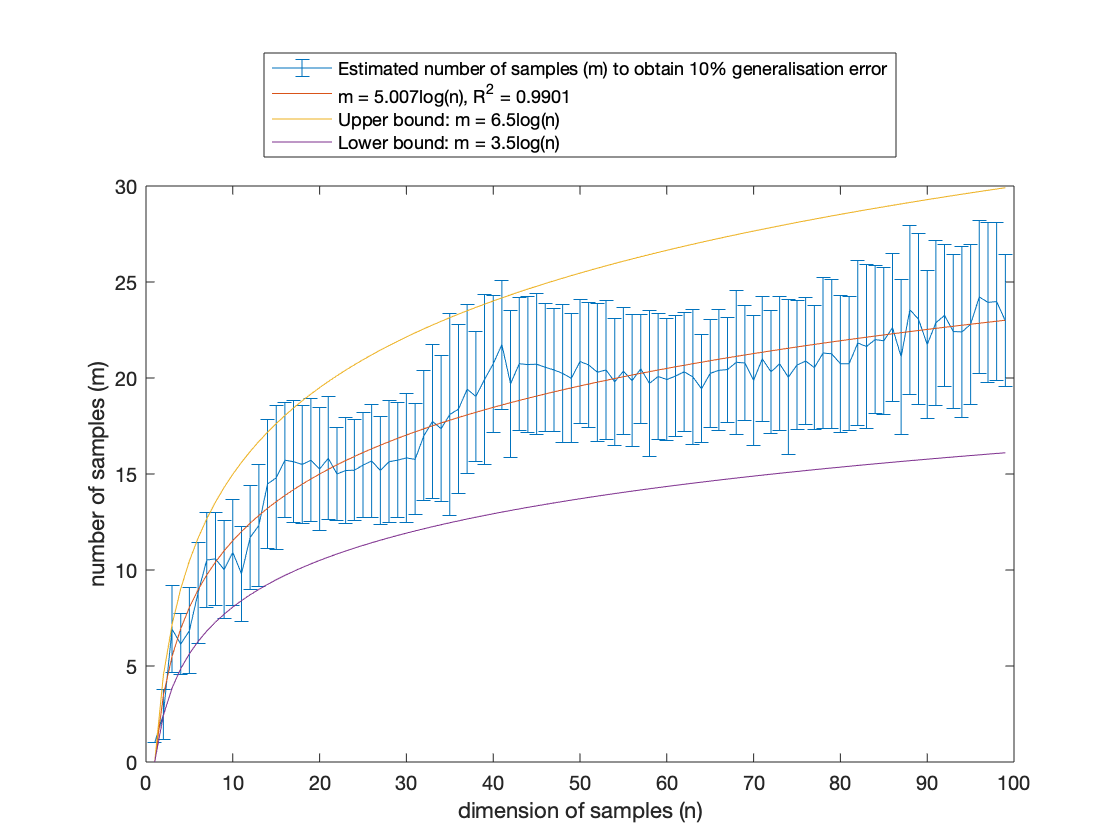

% Winnow Results:
m_winnow_mean = [1.0, 2.48, 6.92, 6.14, 6.84, 8.82, 10.52, 10.58, 10.02, 10.92, 9.8, 11.7, 12.32, 14.48, 14.8, 15.72, 15.64, 15.5, 15.72, 15.26, 15.82, 15.0, 15.18, 15.2, 15.46, 15.68, 15.18, 15.64, 15.72, 15.84, 15.76, 16.98, 17.74, 17.36, 18.1, 18.38, 19.42, 19.04, 19.92, 20.74, 21.74, 19.7, 20.74, 20.7, 20.72, 20.56, 20.42, 20.24, 19.98, 20.86, 20.68, 20.3, 20.42, 19.8, 20.36, 19.86, 20.48, 19.72, 20.08, 19.92, 20.1, 20.32, 20.06, 19.44, 20.24, 20.4, 20.44, 20.82, 20.78, 19.88, 21.0, 20.32, 20.74, 20.04, 20.68, 20.88, 20.54, 21.3, 21.26, 20.74, 20.74, 21.82, 21.64, 22.0, 21.94, 22.62, 21.1, 23.56, 23.06, 21.74, 22.88, 23.26, 22.42, 22.4, 22.8, 24.22, 23.94, 23.98, 22.98];
m_winnow_std = [0.0, 1.2843675486401858, 2.2789471253190583, 1.5749285698088025, 2.2392856003645445, 2.628231344459616, 2.4919069003476033, 2.425613324501661, 2.5572641631243336, 2.748381341808301, 2.4657656011875906, 2.692582403567252, 3.171371942866368, 3.348074073254652, 3.757658845611187, 2.9869047524151147, 3.179685519041152, 3.054504869860253, 3.2064934118129726, 3.198812279581282, 3.1918019988714836, 2.4331050121192876, 2.7618110000505105, 2.615339366124404, 2.721837614553815, 2.955943165894771, 2.826234243653558, 3.179685519041152, 2.986904752415115, 3.3428131865241886, 2.8952374686716116, 3.3852030958274866, 4.014025410980852, 3.809251895057611, 5.277309920783504, 4.417646432207992, 4.418551798949515, 3.399764697740124, 4.44, 3.5822339398760654, 3.357439500571827, 3.817066936798463, 3.4687749999099102, 3.5510561809129406, 3.6662787673607147, 3.3356258783023014, 3.2254612073314415, 3.6031097679643347, 3.355532744587661, 3.231160782133876, 3.264597984438513, 3.601388621073821, 3.6060504710832877, 3.2924155266308657, 3.3212046007435316, 3.435171029221107, 2.8301236722093965, 3.8054697476132957, 3.2975142152839916, 3.1864714026647096, 3.170173496829472, 3.1012255641923243, 3.5009141663285606, 2.8011426240018555, 2.8323841547360766, 3.1496031496047245, 2.73612865194603, 3.74, 3.0152280179117468, 3.3801775101316793, 3.249615361854384, 3.2152138342573733, 3.4917617329938193, 4.024723592993685, 3.3671352809175934, 3.2902279556286067, 3.244749605131342, 3.915354390090379, 3.8771639119335672, 3.559831456684431, 3.480287344458788, 4.30669246638299, 4.250929310162662, 3.8418745424597094, 3.817905184783928, 3.846504907055235, 4.050925820105819, 4.40526957177424, 4.460538084132899, 3.846088922528963, 4.29250509609482, 3.7084228453616235, 4.010436385232909, 4.4362146025637665, 4.166533331199932, 3.976380263505994, 4.173296059471458, 4.110912307505477, 3.4321421881967535];
n_winnow = [1:1:99];

errorbar(n_winnow, m_winnow_mean, m_winnow_std)
hold on
m_winnow = 5.007*log(n_winnow);
R_sq_winnow = 0.9901;
plot(n_winnow, m_winnow)
plot(n_winnow, 1.3*m_winnow);
plot(n_winnow, 0.7*m_winnow);
xlabel('dimension of samples (n)')
ylabel('number of samples (m)')
legend('Estimated number of samples (m) to obtain 10% generalisation error', 'm = 5.007log(n), R^2 = 0.9901', 'Upper bound: m = 6.5log(n)', 'Lower bound: m = 3.5log(n)', 'Location', 'northoutside')
hold off

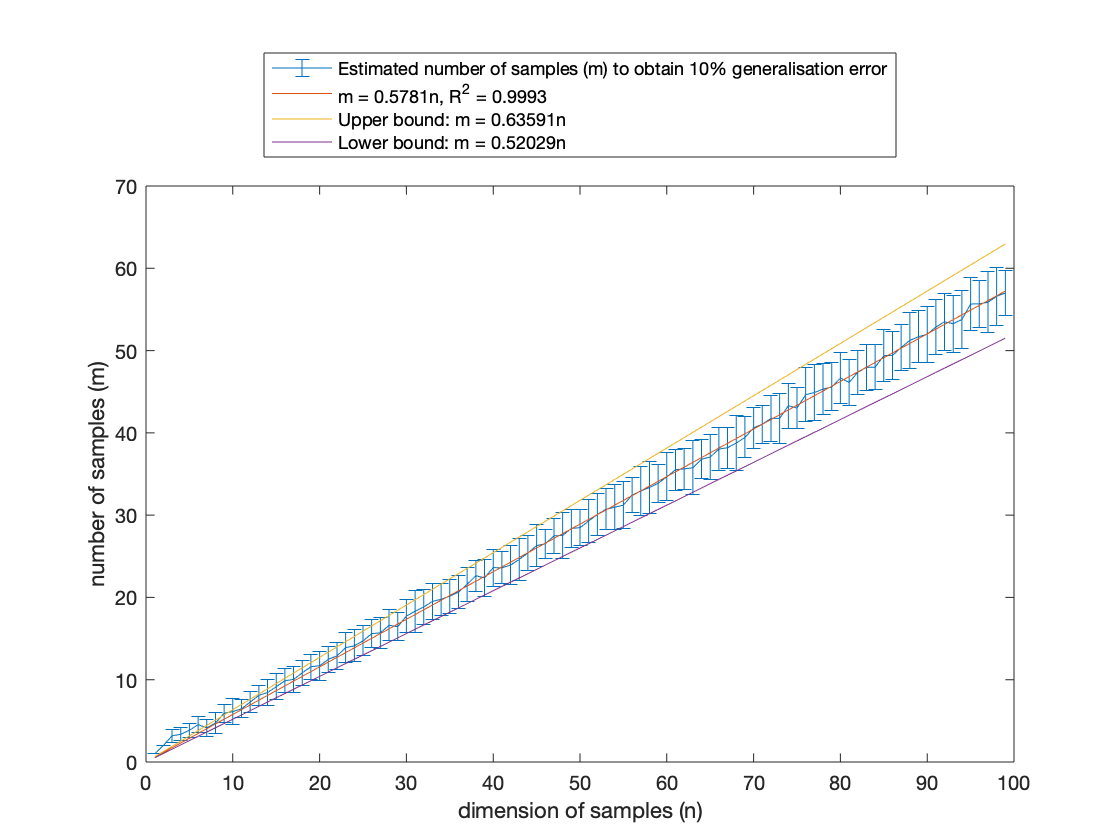

% LS results:
m_LS_mean = [1.0, 2.0, 3.2, 3.36, 3.86, 4.54, 4.16, 4.72, 5.94, 6.12, 6.48, 7.28, 8.1, 8.44, 9.14, 9.88, 10.04, 10.84, 11.58, 11.7, 12.48, 12.9, 13.9, 14.12, 14.72, 15.6, 15.7, 16.62, 16.44, 17.74, 18.32, 18.84, 19.52, 19.78, 20.16, 20.64, 21.6, 22.64, 22.38, 23.62, 23.6, 23.94, 24.62, 25.4, 26.3, 26.52, 27.48, 27.54, 28.38, 28.48, 29.3, 30.08, 30.72, 30.96, 31.22, 32.46, 32.92, 33.36, 33.86, 34.66, 35.52, 35.62, 35.76, 36.8, 37.06, 38.02, 38.2, 38.76, 39.44, 40.6, 41.06, 41.76, 41.76, 43.3, 43.02, 44.64, 44.9, 45.32, 45.58, 46.66, 46.12, 47.36, 47.96, 47.98, 49.38, 49.42, 50.38, 51.24, 51.68, 51.98, 52.86, 53.5, 53.26, 53.78, 55.66, 55.68, 55.86, 56.6, 57.0];
m_LS_std = [0.0, 0.0, 0.8, 0.7939773296511683, 0.8720091742636656, 0.9635351576356723, 1.0071742649611335, 1.2655433615645102, 1.1029052543169788, 1.5829087149927503, 1.1178550889985697, 1.2655433615645102, 1.2206555615733703, 1.5640971836813724, 1.587576769797291, 1.4372195378577346, 1.5742934923323542, 1.5409088227406578, 1.5111584959890871, 1.7578395831246945, 1.5904716281656834, 1.6278820596099706, 1.824828759089466, 1.9456618411224493, 1.8115186998758803, 1.6733200530681511, 1.857417562100671, 1.8749933333214814, 1.6871277367170514, 1.9980990966416055, 2.556873090319502, 2.1666564102321346, 2.1562931155109686, 1.9523319389898839, 2.0529003872570146, 2.037253052519495, 2.08806130178211, 1.862900963551203, 2.226117696798622, 2.2529092303064497, 1.9287301521985911, 2.3867132211474424, 2.560390595202225, 2.172556098240043, 2.5553864678361276, 1.7577258034175864, 2.09990475974507, 2.765574081452167, 2.3485314560380064, 2.2021807373601288, 2.6400757564888178, 2.606453529223186, 2.506312031651287, 2.7273430293969256, 2.8091991741419835, 2.1091230405075945, 2.9382988275531132, 3.116151472569971, 2.3410254163507065, 2.9024816967553817, 2.4838679514016038, 2.4810481655945336, 3.2592023564056283, 2.3748684174075834, 2.7452504439486027, 2.6114363863590473, 2.5059928172283334, 3.3320264104595565, 2.4912647390432037, 2.5059928172283334, 2.3013908837917993, 2.7608694282779838, 3.04998360651332, 2.7586228448267445, 2.5415743152620975, 3.2848744268236496, 3.442382895611701, 3.0688108446106614, 2.9126620126612703, 3.056861135216973, 2.7758962516635957, 2.6889403117213293, 2.8281442678901656, 2.7385397568777416, 3.1867852139734802, 2.898896341713515, 2.8205673188208076, 3.3856166351198125, 3.171371942866368, 3.373366271248943, 3.2863962025294517, 3.4539832078341086, 3.4572243201736277, 3.505937820327109, 3.2348724858949227, 2.852647892748069, 3.7202688074922756, 3.4985711369071804, 2.7422618401604177];
n_LS = [1:1:99];
errorbar(n_LS, m_LS_mean, m_LS_std)
hold on
m_LS = 0.5781*n_LS;
R_sq_LS = 0.9993;
plot(n_LS, m_LS)
plot(n_LS, 1.1*m_LS)
plot(n_LS, 0.9*m_LS)
xlabel('dimension of samples (n)')
ylabel('number of samples (m)')
legend('Estimated number of samples (m) to obtain 10% generalisation error', 'm = 0.5781n, R^2 = 0.9993', 'Upper bound: m = 0.63591n', 'Lower bound: m = 0.52029n', 'Location', 'northoutside')
hold off

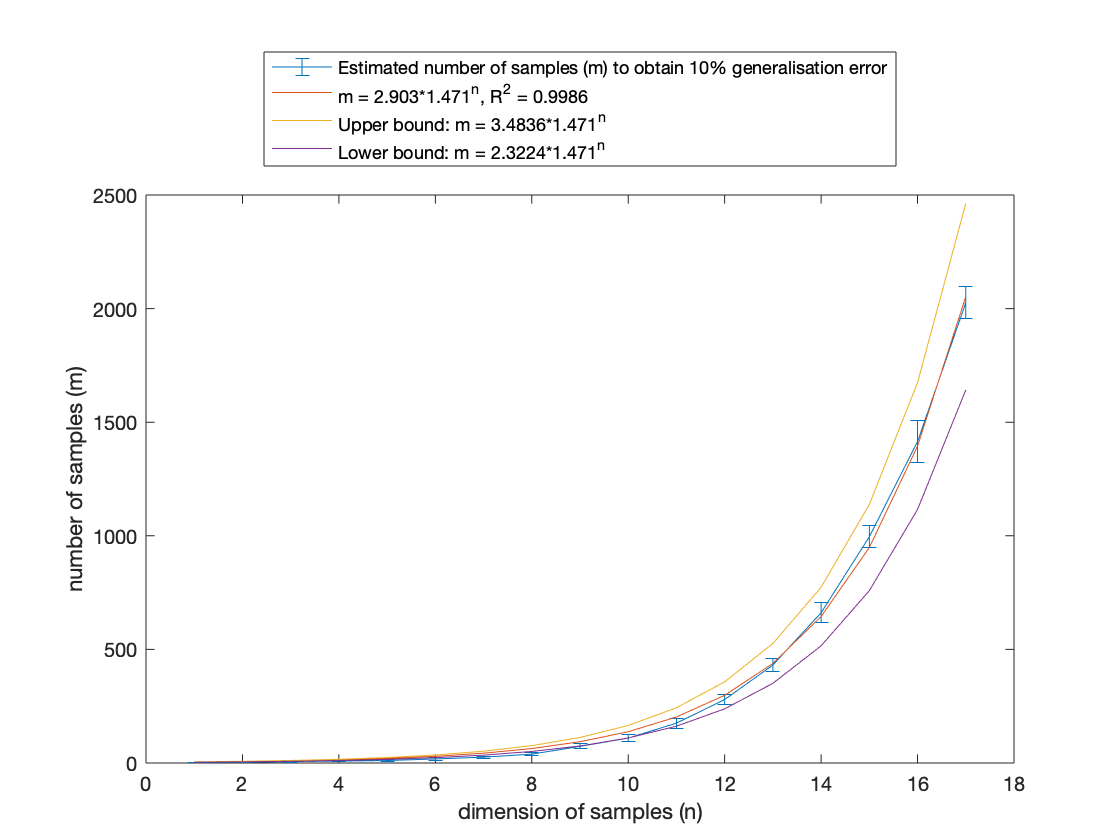

% 1NN Results
m_1NN_mean = [2.3, 2.8, 6.3, 8.4, 10.8, 17.8, 25.8, 38.9, 73.3, 109.6, 175.5, 279.2, 431.4, 661.4, 996.0, 1414.9, 2026.1];
m_1NN_std = [0.45825756949558405, 0.7483314773547882, 3.318132004607412, 2.4979991993593593, 3.867815921162743, 4.894895300208167, 4.445222154178574, 6.949100661236676, 10.780074211247342, 16.16910634512619, 21.914607000811127, 21.871442567878322, 30.295874306578444, 44.9047881634019, 49.24428900898052, 94.40916269091682, 71.46110830374799];
n_1NN = 1:1:17;

errorbar(n_1NN, m_1NN_mean, m_1NN_std)
hold on
m_1NN = 2.903*1.471.^n_1NN;
R_sq_1NN = 0.9987;
plot(n_1NN, m_1NN)
plot(n_1NN, 1.2*m_1NN)
plot(n_1NN, 0.8*m_1NN)
xlabel('dimension of samples (n)')
ylabel('number of samples (m)')
legend('Estimated number of samples (m) to obtain 10% generalisation error', 'm = 2.903*1.471^n, R^2 = 0.9986', 'Upper bound: m = 3.4836*1.471^n', 'Lower bound: m = 2.3224*1.471^n', 'Location', 'northoutside')
hold off

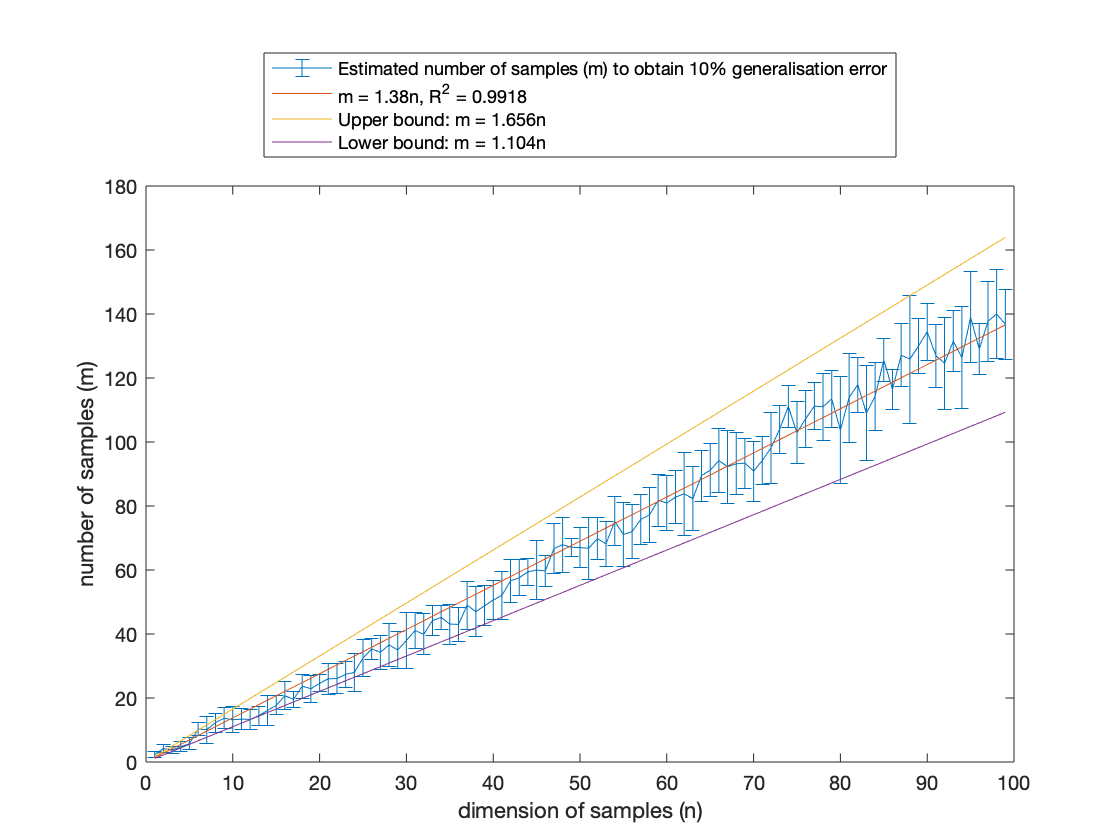

% Perceptron Results:
m_Perceptron_mean = [2.3, 4.2, 3.7, 4.8, 5.7, 10.3, 10.1, 12.3, 13.7, 13.2, 13.4, 13.3, 14.5, 16.1, 17.7, 20.7, 19.6, 23.7, 22.9, 24.6, 26.0, 26.1, 27.4, 28.0, 32.5, 35.3, 34.3, 36.6, 35.0, 38.0, 41.1, 39.9, 44.2, 45.2, 43.1, 43.0, 49.0, 47.0, 48.8, 50.6, 52.1, 56.6, 57.6, 59.4, 60.0, 59.7, 66.7, 67.9, 67.1, 67.0, 66.8, 69.8, 68.2, 75.2, 71.1, 72.0, 75.8, 77.2, 81.8, 80.9, 82.8, 83.8, 82.3, 89.5, 91.2, 94.2, 92.3, 93.2, 93.4, 90.9, 94.2, 98.2, 104.0, 111.1, 102.9, 107.3, 111.2, 111.0, 113.5, 103.7, 113.9, 117.9, 109.0, 114.3, 125.6, 116.5, 127.1, 125.9, 130.0, 134.5, 127.0, 124.6, 131.5, 126.4, 139.0, 129.0, 137.7, 140.0, 136.8];
m_Perceptron_std = [0.9, 1.2489995996796797, 1.004987562112089, 1.661324772583615, 1.9000000000000001, 2.0518284528683193, 4.205948168962618, 2.9342801502242417, 3.195309061734091, 4.093897898091744, 3.1999999999999997, 3.1953090617340916, 2.9748949561287032, 4.592385001282014, 2.9342801502242417, 4.382921400162226, 2.4576411454889016, 3.7960505792204615, 4.2296571965113205, 2.690724809414742, 4.898979485566356, 4.678675026115834, 4.1036569057366385, 5.89915248150105, 5.678908345800274, 3.318132004607412, 5.348831648126533, 6.740919818541088, 5.779273310719955, 8.763560920082657, 5.503635162326805, 6.363175307973213, 4.621688003316537, 3.6823905279043943, 6.252199612936233, 5.385164807134504, 7.469939758793239, 7.810249675906654, 6.273754856543249, 6.019966777316964, 7.529276193632426, 6.7111846942250075, 5.678027826631356, 4.294182110716777, 9.154233993076646, 4.879549159502341, 7.874642849044013, 8.5492689745966, 2.8442925306655784, 6.244997998398398, 9.651942809610922, 6.569627082262737, 7.05407683541936, 7.678541528180986, 9.863569333664158, 8.342661445845684, 7.896834808959853, 8.669486720677297, 8.096912991998865, 8.711486669908874, 8.364209466530593, 12.967652061957862, 10.109896141899778, 7.978095010715277, 8.268010643437755, 10.057832768544126, 11.36705766678431, 9.651942809610922, 7.8, 9.374966666607408, 7.4269778510508555, 11.15168148756052, 7.496665925596525, 6.624952830020754, 9.627564593395363, 8.944830909525345, 7.4404300950953095, 10.44030650891055, 8.980534505250787, 16.805058762170393, 13.910068296022132, 8.5492689745966, 14.805404418657398, 10.630616162763097, 6.7111846942250075, 6.216912416947821, 9.863569333664158, 20.012246250733575, 8.717797887081348, 8.891006692158093, 9.818350166906862, 14.40971894243604, 9.468368391650168, 15.825296205758677, 14.24078649513432, 7.962411694957753, 12.51439171514141, 13.957077057894322, 10.92520022699813];
n_Perceptron = 1:1:99;

errorbar(n_Perceptron, m_Perceptron_mean, m_Perceptron_std)
hold on
m_Perceptron = 1.38*n_Perceptron;
R_sq_1NN = 0.9918;
plot(n_Perceptron, m_Perceptron)
plot(n_Perceptron, 1.2*m_Perceptron)
plot(n_Perceptron, 0.8*m_Perceptron)
xlabel('dimension of samples (n)')
ylabel('number of samples (m)')
legend('Estimated number of samples (m) to obtain 10% generalisation error', 'm = 1.38n, R^2 = 0.9918', 'Upper bound: m = 1.656n', 'Lower bound: m = 1.104n', 'Location', 'northoutside')
hold off

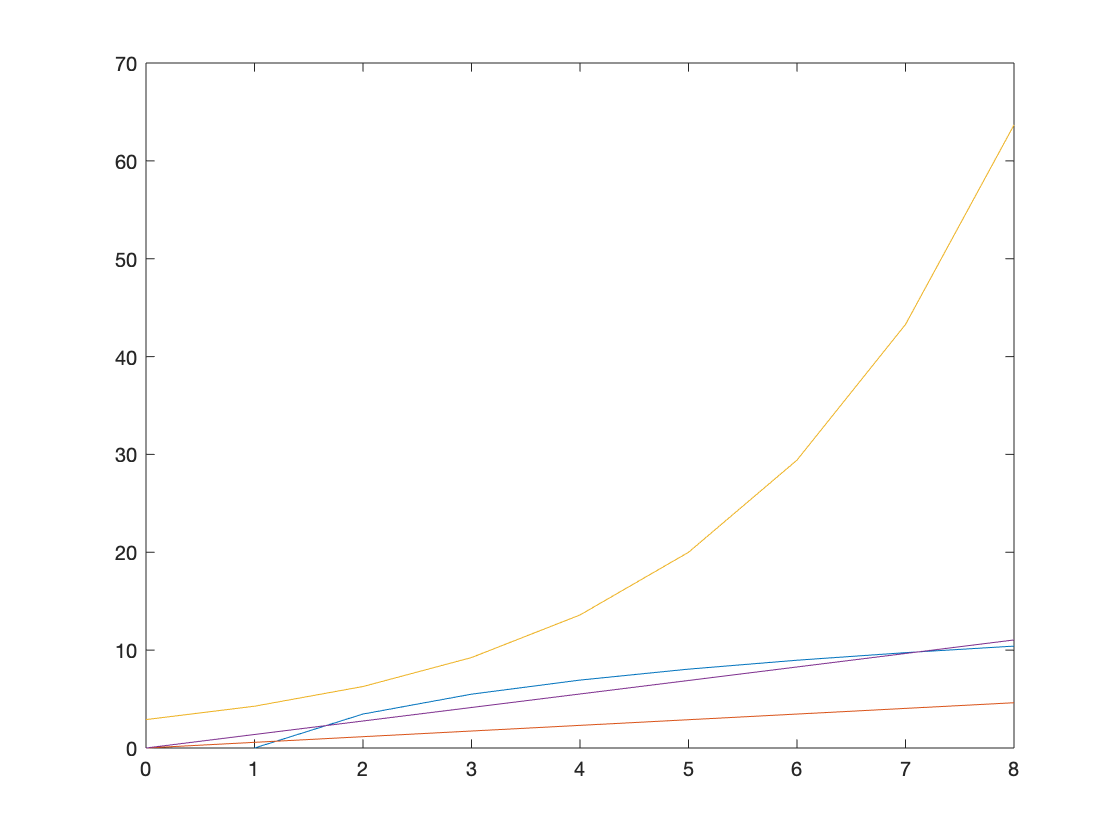

% All curves:
n = 0:1:8;
m_winnow = 5.007*log(n);
m_LS = 0.5781*n;
m_1NN = 2.903*exp(0.386*n);
m_Perceptron = 1.38*n;

plot(n, m_winnow)
hold on
plot(n, m_LS)
plot(n, m_1NN)
plot(n, m_Perceptron)